# Calculating the Fourier Series of a Sawtooth Wave with period 5

In this script we will plot a sawtooth wave and its approximated Fourier series over the interval 0<t<5.

First, clear any previously-assigned variables.

clear

## 1. Defining the sawtooth wave f(t) in the first period

Declare and plot the straight line** f(t)=t **as this is how the function behaves during the first period 0< t < 5.

In this case, we will not need Heaviside step functions, as within one full period there is only one type of behaviour.

syms t
f = t

$$f = t$$

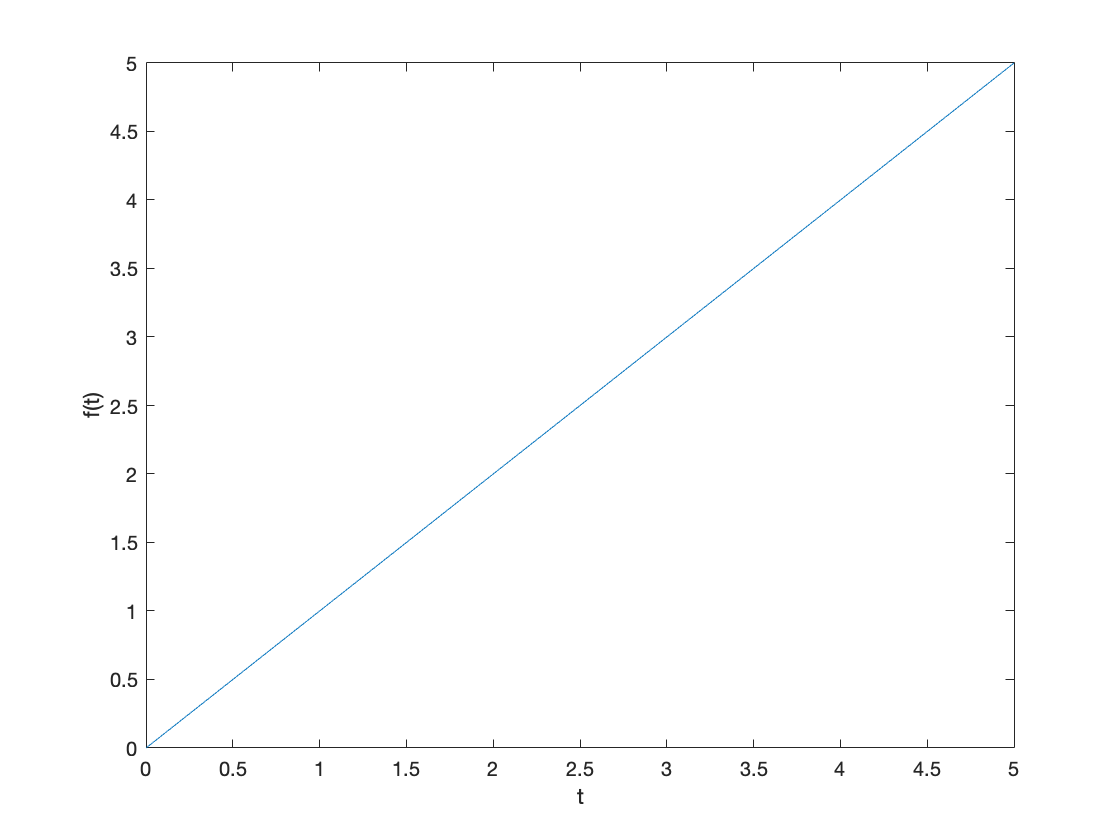

fplot(f, [0 5])
xlabel('t')
ylabel('f(t)')

## 2. Calculating the first Fourier coefficients

From the function definition, we are told that this sawtooth wave has period of T = 5.

We need to store that, and calculate the angular frequency.

T = 5

T = 5

w = 2*pi/T

w = 1.2566

Let's start by calculating the first few **a_k** coefficients of the cosine terms:


a0 = int(f, t, 0, T)*2/T

$$a0 = 5$$


a1 = int(f * cos(w*t), t, 0, T)*2/T

$$a1 = 0$$


a2 = int(f * cos(2 * w * t), t, 0, T)*2/T

$$a2 = 0$$


a3 = int(f * cos(3 * w * t), t, 0, T)*2/T

$$a3 = 0$$


a4 = int(f * cos(4 * w * t), t, 0, T)*2/T

$$a4 = 0$$


a5 = int(f * cos(5 * w * t), t, 0, T)*2/T

$$a5 = 0$$

See the pattern? All the a_k terms are zero for k>0, so we will not need any cosine terms in the final Fourier series.

Next, let's look at the **b_k** terms:

b1 = int(f * sin(t), t, 0, T)*2/T

$$b1 = \frac{2\,\sin\left(5\right)}{5}-2\,\cos\left(5\right)$$


b2 = int(f * sin(2 * w * t), t, 0, T)*2/T

$$b2 = -\frac{5}{2\,\pi }$$


b3 = int(f * sin(3 * w * t), t, 0, T)*2/T

$$b3 = -\frac{5}{3\,\pi }$$


b4 = int(f * sin(4 * w * t), t, 0, T)*2/T

$$b4 = -\frac{5}{4\,\pi }$$


b5 = int(f * sin(5 * w * t), t, 0, T)*2/T

$$b5 = -\frac{1}{\pi }$$

## 3. Plotting the approximate Fourier Series

Now we shall construct the first five terms of the Fourier series.

(This is specifically called the **"5th partial sum"**, as the actual Fourier series ought to include all of the infinitely-many terms.)

As we know that a_1 , a_2, a_3 ... are all zero we don't need to include these in the sum.


FourierApprox = a0/2 + b1 * sin(w*t) + b2 * sin(2 * w * t) + b3 * sin(3 * w * t)...
                + b4 * sin(4 * w * t) + b5 * sin(5 * w * t)

$$FourierApprox = \frac{5}{2}-\frac{5\,\sin\left(\frac{4\,\pi \,t}{5}\right)}{2\,\pi }-\frac{5\,\sin\left(\frac{6\,\pi \,t}{5}\right)}{3\,\pi }-\frac{5\,\sin\left(\frac{8\,\pi \,t}{5}\right)}{4\,\pi }-\sin\left(\frac{2\,\pi \,t}{5}\right)\,\left(2\,\cos\left(5\right)-\frac{2\,\sin\left(5\right)}{5}\right)-\frac{\sin\left(2\,\pi \,t\right)}{\pi }$$

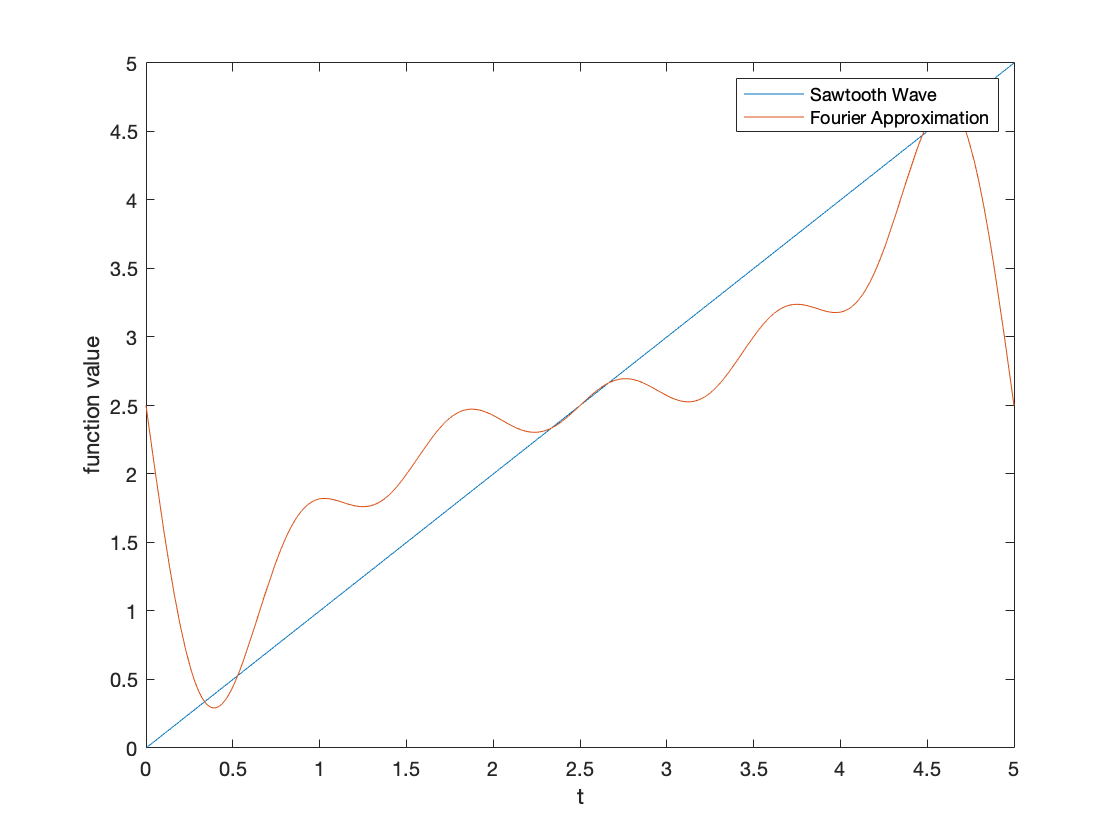


% Plot both the sawtooth wave and the Fourier partial sum on the same graph.
fplot(f, [0, 5])
hold on
fplot(FourierApprox, [0, 5])
hold off
legend('Sawtooth Wave', 'Fourier Approximation')
xlabel('t')
ylabel('function value')